# Use a trained CNN classifier on test data

This example shows how to use a trained CNN network to classify new data and visualize a grad-CAM. 

clear
close all

dataset_path='/Users/retico/Desktop/CMEPDA/DATASETS/IMAGES/Mammography_micro/Test'

dataset_path = '/Users/retico/Desktop/CMEPDA/DATASETS/IMAGES/Mammography_micro/Test'

imdsValidation = imageDatastore(dataset_path, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');

We load a network that I have pretrained with 500 epochs, which achieved on the validation set an accuracy of 88%. 

load net_micro_train280_epochs500_acc88_500epochs

Evaluate network performace on test data set

YPred = classify(net,imdsValidation);
YValidation = imdsValidation.Labels;

accuracy = sum(YPred == YValidation)/numel(YValidation)

accuracy = 0.8105

We can visualize some correctly classified images:

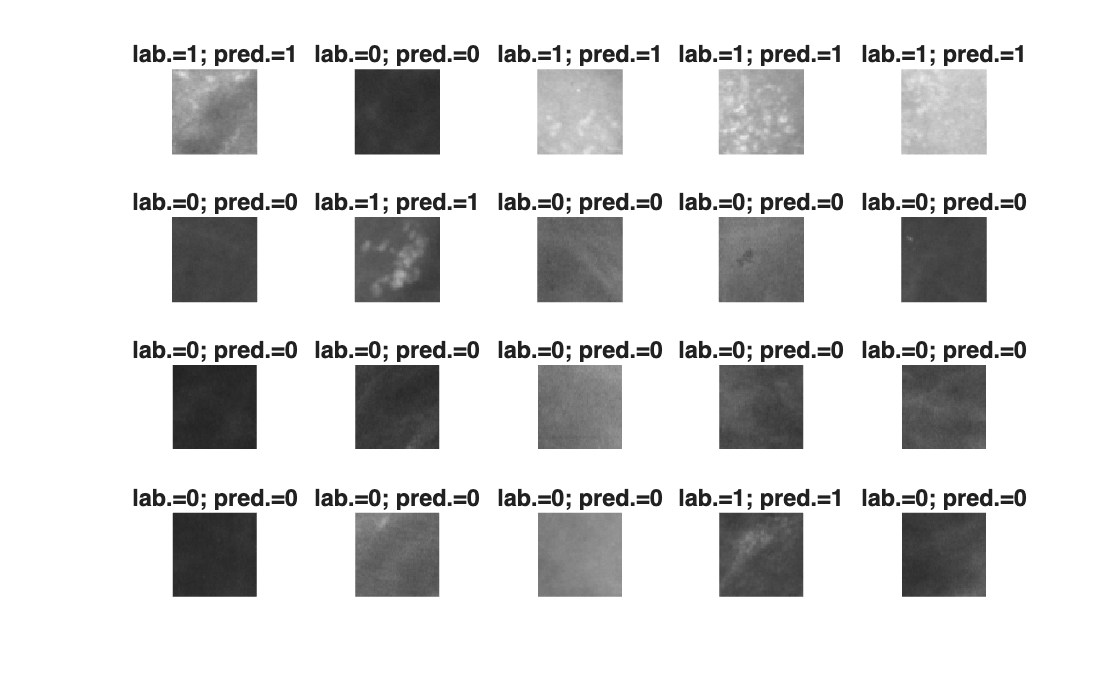

figure; title('Correctly classified ')
idx_outOK=find(YPred == YValidation);
perm = randperm(sum(YPred == YValidation),20);
for i = 1:20
    subplot(4,5,i);
    imshow(imdsValidation.Files{idx_outOK(perm(i))});
    title(strcat('lab.= ',char(YValidation(idx_outOK(perm(i)))), ...
        '; pred.= ',char(YPred(idx_outOK(perm(i))))))
    
end

... and some misclassified images

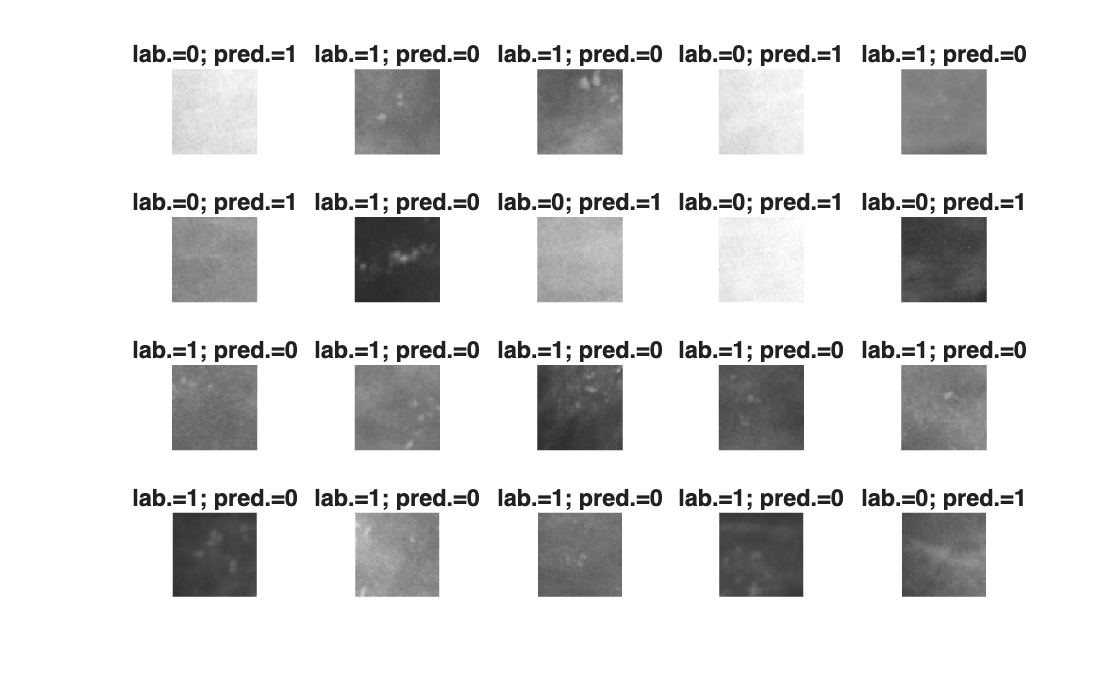

figure; title('Misclassified ')
idx_outOK=find(YPred ~= YValidation);
if(sum(YPred ~= YValidation)>20)
    perm = randperm(sum(YPred ~= YValidation),20);
    for i = 1:20
        subplot(4,5,i);
        imshow(imdsValidation.Files{idx_outOK(perm(i))});
        title(strcat('lab.= ',char(YValidation(idx_outOK(perm(i)))), ...
            '; pred.= ',char(YPred(idx_outOK(perm(i))))))
    end
else
    for i = 1:sum(YPred ~= YValidation)
        subplot(4,5,i);
        imshow(imdsValidation.Files{idx_outOK(i)});
        title(strcat('lab.= ',char(YValidation(idx_outOK(i))), ...
            '; pred.= ',char(YPred(idx_outOK(i)))))
    end
end

# Visualization of the grad-CAM

Correctly classified positive examples

Label1_cases = find((YPred == "1") & (imdsValidation.Labels=="1"));
Label1_cases(1)

ans = 206

imdsValidation.Files{Label1_cases(2)};
img = imread(imdsValidation.Files{Label1_cases(2)});

% Display the classification result
Y = classify(net,img)

Y = categorical
     1 


disp(['Predicted label: ', char(Y)]);

Predicted label: 1


channel = 1; % Specify the channel for Grad-CAM
map = gradCAM(net,img,channel);

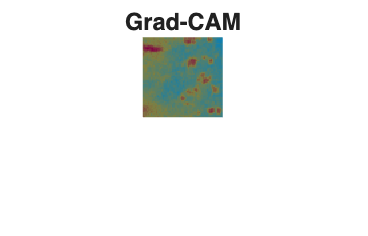

figure
imshow(img);
hold on;
imagesc(map,'AlphaData',0.5);
colormap jet
hold off;
title("Grad-CAM");